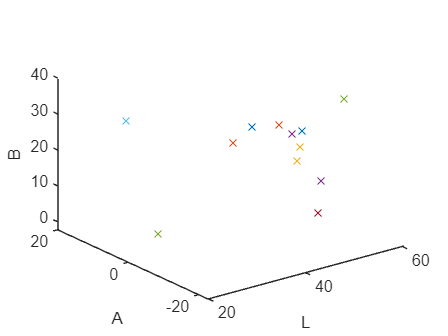

clc
clearvars -except textures

if ~exist('textures', 'var')
    disp("Textures not loaded, loading textures...")
    load("textures\textures.mat");
    disp("done")
end


for i = 1:numel(textures)
    current_diffuse = textures(i).diffuse;

    L = textures(i).avgLAB(1);
    A = textures(i).avgLAB(2);
    B = textures(i).avgLAB(3);

    plot3(L, A, B, 'x');
    %text(L, A, B, textures(i).name);
    hold on
end
xlabel("L");
ylabel("A");
zlabel("B");
hold off